processingOptions = phoPipelineOptions.PhoPostFinalDataStructAnalysis.processingOptions;


curr_cellROI_index =42     

curr_cellROI_index = 42

curr_session_index = 1

curr_session_index = 1

active_fissa_var_name = 'cell_dff';
% active_fissa_var_name = 'fissa_df_raw';
curr_cellROI_compListIndicies = cellROIIndexMapper.getCompListIndicies(curr_cellROI_index);
curr_day_linear_comp_index = curr_cellROI_compListIndicies(curr_session_index); % The linear comp index, not the unique cellROI index

[currentAnm, currentSesh, currentComp] = fnBuildCurrIdentifier(activeCompList, curr_day_linear_comp_index); % TODO: potentially refactor into CellROIIndexMapper?
original.rawDFF = finalDataStruct.(currentAnm).(currentSesh).imgData.(currentComp).imagingDataDFF;
fissa.fissa_df_raw = finalDataStruct.(currentAnm).(currentSesh).imgData.(currentComp).fissa_df_raw;  % 520x150 double. %assumes you have this field
fissa.cell_dff = finalDataStruct.(currentAnm).(currentSesh).imgData.(currentComp).fissa_df_result.cell_dff;  % 520x150 double. %assumes you have this field

% fissa.neuropilCorrectedDFF = squeeze(finalDataStruct.(currentAnm).(currentSesh).imgData.(currentComp).fissa_df_result(1,:,:));  % 520x150 double. %assumes you have this field
% fissa.imgDataNeuropil = squeeze(sum(finalDataStruct.(currentAnm).(currentSesh).imgData.(currentComp).fissa_df_result(2:end,:,:),1)); % 520x150 double
%       

fissa.neuropilCorrectedDFF = finalDataStruct.(currentAnm).(currentSesh).imgData.(currentComp).fissa_raw.measured_cell_signal;  % 520x150 double. %assumes you have this field

active_fissa_var = fissa.(active_fissa_var_name);

[numTrials, outputs.numFramesPerTrial] = size(original.rawDFF);
% Smooth the curve
if processingOptions.smoothValue>0
    for i = 1:numTrials
        original.rawDFF(i,:) = smooth(original.rawDFF(i,:), processingOptions.smoothValue);
        active_fissa_var(i,:) = smooth(active_fissa_var(i,:), processingOptions.smoothValue);
    end
end

[~, outputs.numFramesPerTrial] = size(original.rawDFF);


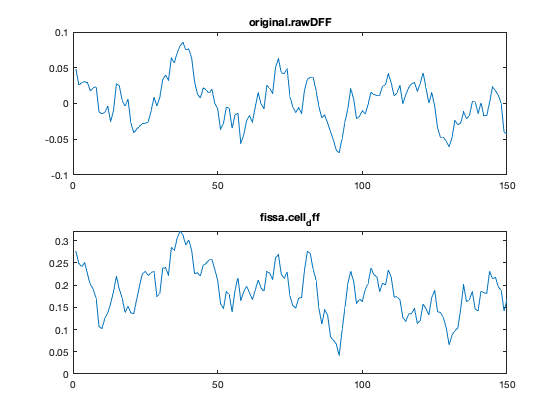

trial_index = 75;

figure;
clf;
subplot(2,1,1)
plot(original.rawDFF(trial_index,:));
title('original.rawDFF')
subplot(2,1,2)
plot(active_fissa_var(trial_index,:));
title(['fissa.' active_fissa_var_name])

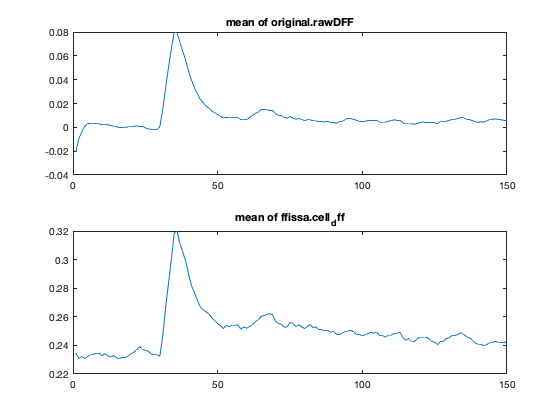

mean_dim = 1;
figure;
clf;
subplot(2,1,1)
plot(mean(original.rawDFF, mean_dim));
title('mean of original.rawDFF')
subplot(2,1,2)
plot(mean(active_fissa_var, mean_dim));
title(['mean of ffissa.' active_fissa_var_name])